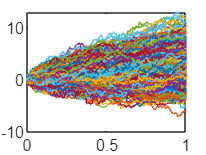

n=1000;m=1000;
szigma = 3;
mu = 3;
[w,t] = wiener(n,m);
%egyetlen folytonos Lévy-folyamat
w = mu*t'+szigma*w;
plot(t,w);

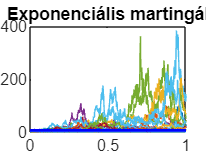

E = exp(w)./exp(mu*t'+szigma^2*t'/2); %exponenciális martingál képlete
plot(t,E);
hold on
plot(t,ones(size(t)),'r','LineWidth',3);
plot(t,mean(E,2),'b','LineWidth',3);
hold off
title('Exponenciális martingál');


%mu,szigma paraméterű lognormális eloszlás várható értéke
%exp(mu+szigma^2/2)

mu = 0.5;
x =0:0.1:exp(mu)+1;
szigma =1;
y=lognpdf(x,mu,szigma); %standard lognorm. sűrűségfüggvénye
area(x,y);
hold on
x = exp(mu):0.1:8

x =     1.6487    1.7487    1.8487    1.9487    2.0487    2.1487    2.2487    2.3487    2.4487    2.5487    2.6487    2.7487    2.8487    2.9487    3.0487    3.1487    3.2487    3.3487    3.4487    3.5487    3.6487    3.7487    3.8487    3.9487    4.0487    4.1487    4.2487    4.3487    4.4487    4.5487    4.6487    4.7487    4.8487    4.9487    5.0487    5.1487    5.2487    5.3487    5.4487    5.5487    5.6487    5.7487    5.8487    5.9487    6.0487    6.1487    6.2487    6.3487    6.4487    6.5487


y=lognpdf(x,mu,szigma);
area(x,y,"FaceColor","r");
E = exp(mu+(szigma)^2*0.5)

E = 2.7183

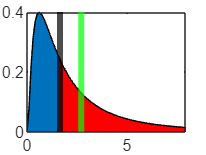

xline(E,"g","LineWidth",3);
xline(exp(mu),"k","LineWidth",3);
hold off